# Predicting OKR Behavior from oDSGC activity

Using absolute firing rates here. A second script, 'behaviorPredicitions_normedTC.mlx' does the same thing with normalized firing rates

downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
mustHave_2b = {'Extracellular', '_Intensity0d1'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upPDHighC = [];
upPDLowC = [];
upNDHighC = [];
upNDLowC = [];
cnames = {};
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_LowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass || pass_LowC
        continue
    end
    
    cnames{end + 1} = struct_i.cellID;
    %Call the PD of the cell whatever it is in the high contrast condition
    %(round to closest probed direction)
    orientations = loc.Analysis_Results.Orientation;
    orientations_lowC = loc_LowC.Analysis_Results.Orientation;
    [~, roundedPD_Index] = min(abs(orientations - mod(loc.Analysis_Results.PreferredDirection, 360)));
    roundedPD = orientations(roundedPD_Index);
    
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    spikes_LowC = loc_LowC.Analysis_Results.mean_spikesByOrientation;
    
    upPDHighC(end+1) = spikes(orientations == mod(roundedPD,360));
    upPDLowC(end+1) = spikes_LowC(orientations_lowC == mod(roundedPD, 360));
    
    upNDHighC(end + 1) = spikes(orientations == mod(roundedPD + 180, 360));
    upNDLowC(end + 1) = spikes_LowC(orientations_lowC == mod(roundedPD + 180, 360));
end

downPDHighC = [];
downPDLowC = [];
downNDHighC = [];
downNDLowC = [];
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_LowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass || pass_LowC
        continue
    end
    
    cnames{end + 1} = struct_i.cellID;
    
    %Call the PD of the cell whatever it is in the high contrast condition
    %(round to closest probed direction)
    orientations = loc.Analysis_Results.Orientation;
    orientations_lowC = loc_LowC.Analysis_Results.Orientation;
    [~, roundedPD_Index] = min(abs(orientations - mod(loc.Analysis_Results.PreferredDirection, 360)));
    roundedPD = orientations(roundedPD_Index);
    
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    spikes_LowC = loc_LowC.Analysis_Results.mean_spikesByOrientation;
    
    downPDHighC(end+1) = spikes(orientations == mod(roundedPD,360));
    downPDLowC(end+1) = spikes_LowC(orientations_lowC == mod(roundedPD, 360));
    
    downNDHighC(end + 1) = spikes(orientations == mod(roundedPD + 180, 360));
    downNDLowC(end + 1) = spikes_LowC(orientations_lowC == mod(roundedPD + 180, 360));
end


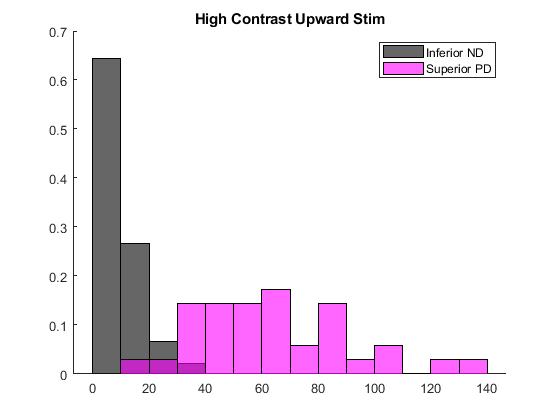

% High contrast upward moving stimulus
figure
title('High Contrast Upward Stim')
hold on
h1 = histogram(upNDHighC, 'FaceColor','k', 'Normalization', 'probability');
h2 = histogram(downPDHighC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 10;
h2.BinWidth = h1.BinWidth;
legend({'Inferior ND', 'Superior PD'})

diffOfMedians1 = abs(median(upNDHighC) - median(downPDHighC))

diffOfMedians1 = 56.4000

[~, ~, posE1, negE1] = medianCI95Bootstrap(upNDHighC, 10000); [~, ~, posE2, negE2] = medianCI95Bootstrap(downPDHighC, 10000);
posPropErr1 = sqrt(posE1^2 + posE2^2)

posPropErr1 = 16.7189

negPropErr1 = sqrt(negE1^2 + negE2^2)

negPropErr1 = 7.7878


labels =  [zeros(1, numel(upNDHighC)), ones(1, numel(downPDHighC))];
scores = [upNDHighC, downPDHighC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.99175


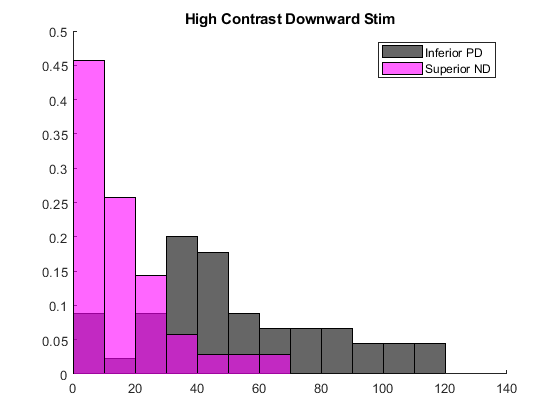


figure
title('High Contrast Downward Stim')
hold on
h1 = histogram(upPDHighC, 'FaceColor','k', 'normalization', 'probability');
h2 = histogram(downNDHighC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 10;
h2.BinWidth = h1.BinWidth;
legend({'Inferior PD', 'Superior ND'})
xlim([0 140])

diffOfMedians2 = abs(median(upPDHighC) - median(downNDHighC))

diffOfMedians2 = 31.2000

[~, ~, posE1, negE1] = medianCI95Bootstrap(upPDHighC, 10000); [~, ~, posE2, negE2] = medianCI95Bootstrap(downNDHighC, 10000);
posPropErr2 = sqrt(posE1^2 + posE2^2)

posPropErr2 = 9.9358

negPropErr2 = sqrt(negE1^2 + negE2^2)

negPropErr2 = 13.4462


labels =  [zeros(1, numel(upPDHighC)), ones(1, numel(downNDHighC))];
scores = [upPDHighC, downNDHighC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.86698


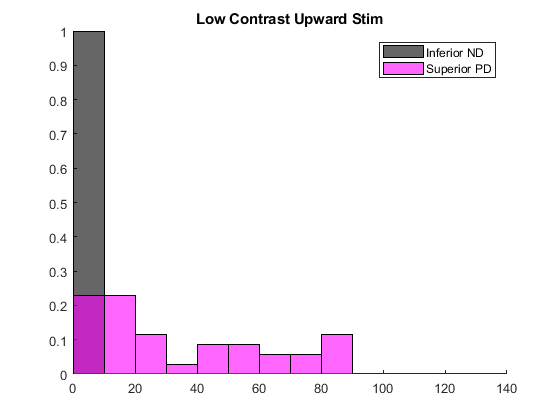


figure
title('Low Contrast Upward Stim')
hold on
h1 = histogram(upNDLowC, 'FaceColor','k', 'normalization', 'probability');
h2 = histogram(downPDLowC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 10;
h2.BinWidth = h1.BinWidth;
legend({'Inferior ND', 'Superior PD'})
xlim([0 140])

diffOfMedians3 = abs(median(upNDLowC) - median(downPDLowC))

diffOfMedians3 = 25.2500

[~, ~, posE1, negE1] = medianCI95Bootstrap(upNDLowC, 10000); [~, ~, posE2, negE2] = medianCI95Bootstrap(downPDLowC, 10000);
posPropErr3 = sqrt(posE1^2 + posE2^2)

posPropErr3 = 9.0500

negPropErr3 = sqrt(negE1^2 + negE2^2)

negPropErr3 = 22.1500


labels =  [zeros(1, numel(upNDLowC)), ones(1, numel(downPDLowC))];
scores = [upNDLowC, downPDLowC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.90254


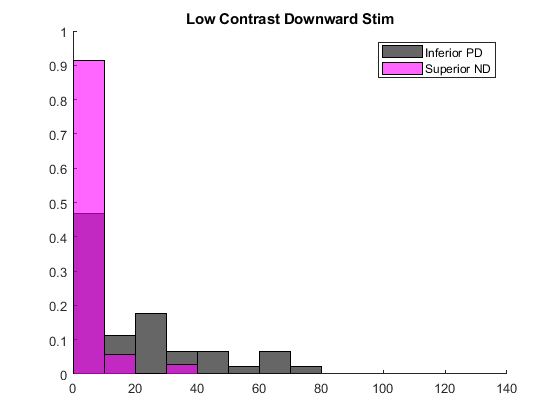

figure
title('Low Contrast Downward Stim')
hold on
h1 = histogram(upPDLowC, 'FaceColor','k', 'normalization', 'probability');
h2 = histogram(downNDLowC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 10;
h2.BinWidth = h1.BinWidth;
legend({'Inferior PD', 'Superior ND'})
xlim([0 140])

diffOfMedians4 = abs(median(upPDLowC) - median(downNDLowC))

diffOfMedians4 = 11.4000

[~, ~, posE1, negE1] = medianCI95Bootstrap(upPDLowC, 10000); [~, ~, posE2, negE2] = medianCI95Bootstrap(downNDLowC, 10000);
posPropErr4 = sqrt(posE1^2 + posE2^2)

posPropErr4 = 10.0180

negPropErr4 = sqrt(negE1^2 + negE2^2)

negPropErr4 = 11.6276

labels =  [zeros(1, numel(upPDLowC)), ones(1, numel(downNDLowC))];
scores = [upPDLowC, downNDLowC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.72825


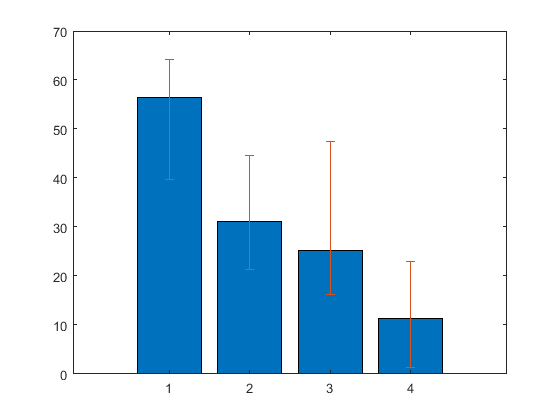


figure
bar(1:4, [diffOfMedians1, diffOfMedians2, diffOfMedians3, diffOfMedians4])
hold on
er = errorbar(1:4, [diffOfMedians1, diffOfMedians2, diffOfMedians3, diffOfMedians4], [posPropErr1, posPropErr2, posPropErr3, posPropErr4],...
    [negPropErr1, negPropErr2, negPropErr3, negPropErr4]);
er.LineStyle = 'none';

## Predictions for Asymmetries

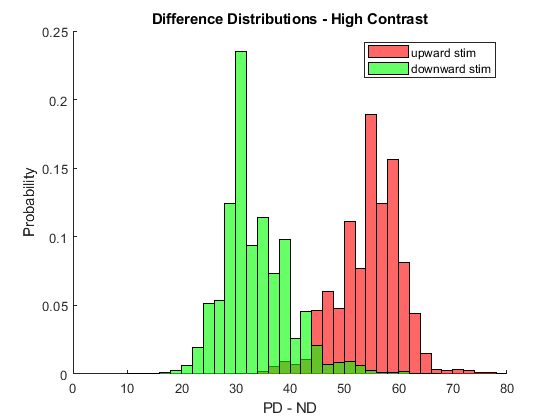


reps = 10000;
results1 = bootstrapSimulation(upNDHighC, 100000);
results2 = bootstrapSimulation(downPDHighC, 100000);
upwardStimHighC_Differences = results2 - results1;

results1 = bootstrapSimulation(upPDHighC, 100000);
results2 = bootstrapSimulation(downNDHighC, 100000);
downwardStimHighC_Differences = results1 - results2;


figure
title('Difference Distributions - High Contrast')
hold on
h1 = histogram(upwardStimHighC_Differences, 'FaceColor', 'r', 'normalization', 'probability');
h2 = histogram(downwardStimHighC_Differences, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 2;
h2.BinWidth = h1.BinWidth;
legend({'upward stim', 'downward stim'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 80])

differenceOfMedians = median(upwardStimHighC_Differences) - median(downwardStimHighC_Differences)

differenceOfMedians = 22.9714


labels =  [zeros(1, numel(upwardStimHighC_Differences)), ones(1, numel(downwardStimHighC_Differences))];
scores = [upwardStimHighC_Differences, downwardStimHighC_Differences];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.98493


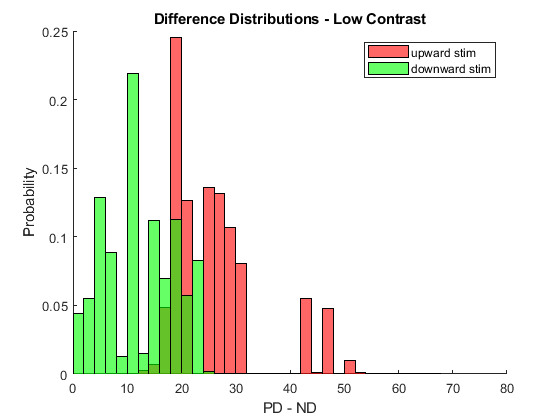


results1 = bootstrapSimulation(upNDLowC, 100000);
results2 = bootstrapSimulation(downPDLowC, 100000);
upwardStimLowC_Differences = results2 - results1;

results1 = bootstrapSimulation(upPDLowC, 100000);
results2 = bootstrapSimulation(downNDLowC, 100000);
downwardStimLowC_Differences = results1 - results2;

figure
title('Difference Distributions - Low Contrast')
hold on
h1 = histogram(upwardStimLowC_Differences, 'FaceColor', 'r', 'normalization', 'probability');
h2 = histogram(downwardStimLowC_Differences, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 2;
h2.BinWidth = h1.BinWidth;
legend({'upward stim', 'downward stim'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 80])


differenceOfMedians = median(upwardStimLowC_Differences) - median(downwardStimLowC_Differences)

differenceOfMedians = 13.8500


labels =  [zeros(1, numel(upwardStimLowC_Differences)), ones(1, numel(downwardStimLowC_Differences))];
scores = [upwardStimLowC_Differences, downwardStimLowC_Differences];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.90833



% topBound1 = prctile(upwardStimHighC_Differences, 97.5);
% lowBound1 = prctile(upwardStimHighC_Differences, 2.5);
% topBound2 = prctile(downwardStimHighC_Differences, 97.5);
% lowBound2 = prctile(downwardStimHighC_Differences, 2.5);
% topBound3 = prctile(upwardStimLowC_Differences, 97.5);
% lowBound3 = prctile(upwardStimLowC_Differences, 2.5);
% topBound4 = prctile(downwardStimLowC_Differences, 97.5);
% lowBound4 = prctile(downwardStimLowC_Differences, 2.5);
% 
% figure
% bar(1:4, [median(upwardStimHighC_Differences), median(downwardStimHighC_Differences), median(upwardStimLowC_Differences), median(downwardStimLowC_Differences)])
% hold on
% er = errorbar(1:4, [median(upwardStimHighC_Differences), median(downwardStimHighC_Differences), median(upwardStimLowC_Differences), median(downwardStimLowC_Differences)],...
%     [topBound1, topBound2, topBound3, topBound4], [lowBound1, lowBound2, lowBound3, lowBound4]);
% er.LineStyle = 'none';

## asymmetry corresponds to the difference of the differences

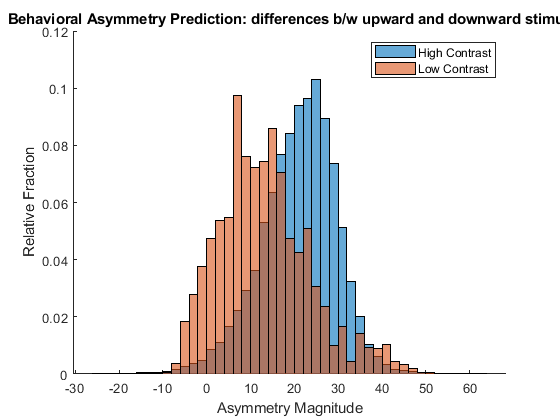


asymmetryDistribution_highC = (upwardStimHighC_Differences - downwardStimHighC_Differences);%./(upwardStimHighC_Differences + downwardStimHighC_Differences);
asymmetryDistribution_lowC = (upwardStimLowC_Differences - downwardStimLowC_Differences);%./(upwardStimLowC_Differences + downwardStimLowC_Differences);

figure
title('Behavioral Asymmetry Prediction: differences b/w upward and downward stimuli')
hold on
h1 = histogram(asymmetryDistribution_highC, 'Normalization', 'probability');
h2 = histogram(asymmetryDistribution_lowC, 'Normalization', 'probability');
h1.BinWidth = 2;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('Asymmetry Magnitude')
ylabel('Relative Fraction')

asymmetryDifference = median(asymmetryDistribution_highC) - median(asymmetryDistribution_lowC)

asymmetryDifference = 9.2000

## Predictions for Change Across Contrast

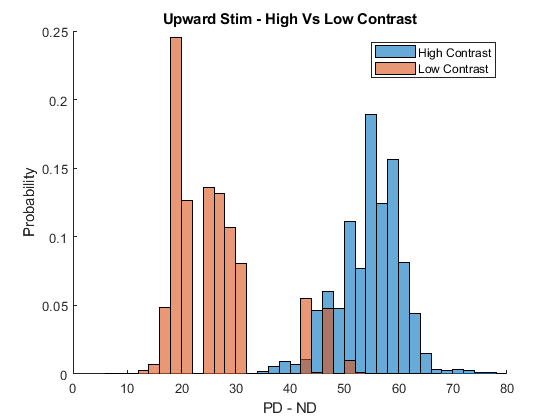

figure
title('Upward Stim - High Vs Low Contrast')
hold on
h1 = histogram(upwardStimHighC_Differences, 'normalization', 'probability');
h2 = histogram(upwardStimLowC_Differences, 'Normalization', 'probability');
h1.BinWidth = 2;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 80])

difference = median(upwardStimHighC_Differences) - median(upwardStimLowC_Differences)

difference = 29.9500

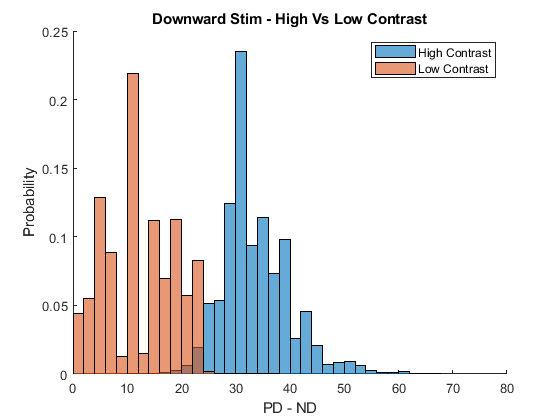


figure
title('Downward Stim - High Vs Low Contrast')
hold on
h1 = histogram(downwardStimHighC_Differences, 'normalization', 'probability');
h2 = histogram(downwardStimLowC_Differences, 'Normalization', 'probability');
h1.BinWidth = 2;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 80])

difference = median(downwardStimHighC_Differences) - median(downwardStimLowC_Differences)

difference = 20.8286

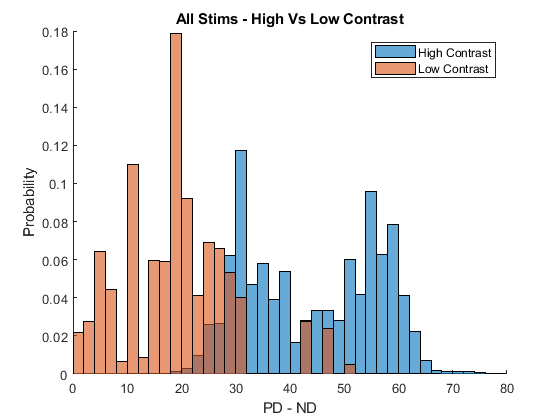


figure
title('All Stims - High Vs Low Contrast')
hold on
h1 = histogram([upwardStimHighC_Differences, downwardStimHighC_Differences], 'normalization', 'probability');
h2 = histogram([upwardStimLowC_Differences, downwardStimLowC_Differences], 'Normalization', 'probability');
h1.BinWidth = 2;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 80])

median([upwardStimHighC_Differences, downwardStimHighC_Differences])

ans = 44.6000

median([upwardStimLowC_Differences, downwardStimLowC_Differences])

ans = 18.8000

## Permutation Testing

predictions = [56.4, 31.8, 25.25, 15]; %enter difference values from above here... order should be high contrast sup stim, high contrast inf. stim, low contrast sup stim, low contrast inf stim

successes = 0; %count the number of times the constraints are successfully met
successfulCombos = zeros(0, 4); %record which combination of data accurately met the results
for i = 1:numel(predictions)
    for j = 1:numel(predictions)
        for k = 1:numel(predictions)
            for m = 1:numel(predictions)
                
                if predictions(i) <= predictions(j)
                    continue
                end
                if predictions(k) <= predictions(m)
                    continue
                end
                if predictions(i) <= predictions(k)
                    continue
                end
                if predictions(j) <= predictions(m)
                    continue
                end
                if abs(predictions(j)-predictions(i)) <= abs(predictions(m) - predictions(k))
                    continue
                end
                successes = successes + 1;
                successfulCombos = [successfulCombos; predictions([i, j, k, m])];
            end
        end
    end
end


## SNR estimation

SNR = @(x) median(x)/iqr(x);
c = [SNR(upwardStimHighC_Differences), SNR(downwardStimHighC_Differences);...
    SNR(upwardStimLowC_Differences), SNR(downwardStimLowC_Differences)]

c =     7.0568    4.1056
    2.7446    1.0556
